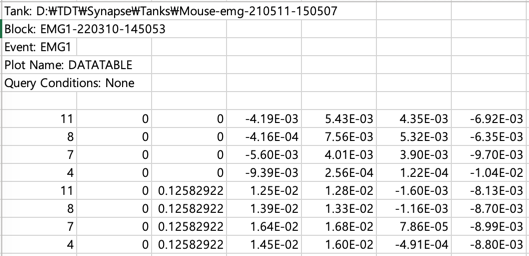

reader = channelReader();

tic 
%                            
reader.readMultiChannelFile( ...
    "./data/height1 - 1,10s - 2x.xlsx", ...#filename
    1, ...#channelColumnIdx
    3, ...#timeColumnIdx
    7, ...#startRowIdx
    4, ...#startColIdx
    nan ... #sample frequency. time column이 있으면 자동으로 frequency 계산하므로 nan을 입력
    ); %일단 파일을 불러옴

This file has 4 channels: 

ans =      4     7     8    11


toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 2.958087초입니다.


%                            organoid, channel, month 


#### 1. 특정 시간 구간의 signal만 사용하기

emg = reader.readSingleChannelFromFile(1, 8, 1);

sampling rate = 1017.252602Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
number of timestamps = 55807

emg.cutTime([10,20]);

startDiff = 5.1710e-04

timestampStart = 1

endDiff = 9.3189e-04

timestampEnd = 10175

ch =   channel - 속성 있음:

              organoidNum: 1
               channelNum: 8
                    month: 1
                       sf: 1.0173e+03
                  msPerTs: 0.9830
              nTimestamps: 10175
                startTime: 9.9995
            endTimeApprox: 20.0009
           durationApprox: 10.0014
                        t: [1×10175 double]
                      raw: [1×10175 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
                      ISI: []
                ISIStruct: []
               th

ch =   channel - 속성 있음:

              organoidNum: 1
               channelNum: 8
                    month: 1
                       sf: 1.0173e+03
                  msPerTs: 0.9830
              nTimestamps: 10175
                startTime: 9.9995
            endTimeApprox: 20.0009
           durationApprox: 10.0014
                        t: [1×10175 double]
                      raw: [1×10175 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
                      ISI: []
                ISIStruct: []
               th

emg

emg =   channel - 속성 있음:

              organoidNum: 1
               channelNum: 8
                    month: 1
                       sf: 1.0173e+03
                  msPerTs: 0.9830
              nTimestamps: 10175
                startTime: 9.9995
            endTimeApprox: 20.0009
           durationApprox: 10.0014
                        t: [1×10175 double]
                      raw: [1×10175 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
                      ISI: []
                ISIStruct: []
               t